# Growth Kinetics Phase Diagram -- Initial Parameter Sweep

Create a phase diagram based on the growth kinetics based on different cutoffs:

Sigmoid function fit:


$$s(x) = k\left(\frac{1}{1+\exp[-(x+a)]}\right) +b$$


(i) the final mass-averaged cluster size of the contact clusters is < 2 (within error) -- essentially no clusters form

(ii) the final mass-averaged cluster size of the contact clusters is = 10648 (within error) -- growth to form full cluster aggregate

(iii) Fit to linear function is better (AIC) than fit to sigmoid function & slope is 0, within confidence intervals -> equilibration

(iv) Fit to linear function is better (AIC) than fit to sigmoid function & slope > 0 -> linear growth

(v) Fit to sigmoid function is better (AIC) than fit to linear function & $s(0) \approx 0$-> equilibrated growth

(vi) Fit to sigmoid function is better (AIC) than fit to linear function & $s(0) \ne 0$ -> lag phase

## Read in Data

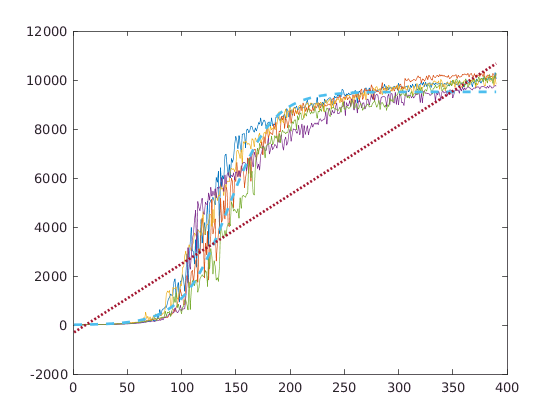

mu2contactMats = {};
mu2opticalMats = {};
mu2alignedMats = {};
paramDict = {};
tstart = 10; %cut off timesteps
fileLocation = '/home/rachael/cluster/scratch/ramansbach/coarsegraining/hoomd/patchy/analyze/';
AAnames = {'250','500','750'};
SCnames = {'2','6','10'};
Signames = {'100','150','200'};
AAparams = [2.5,5,7.5];
SCparams = [2,6,10];
Sigparams = [1.0,1.5,2.0];
fbase = 'mols10000_';
bParams = zeros(length(AAnames),length(Signames),length(SCnames));
cEnds = zeros(length(AAnames),length(Signames),length(SCnames));
oEnds = zeros(length(AAnames),length(Signames),length(SCnames));
aEnds = zeros(length(AAnames),length(Signames),length(SCnames));
for i = 1:length(AAnames)
    for sc = 1:length(SCnames)
        for sig = 1:length(Signames)
    foldname = [fileLocation AAnames{i} '-' SCnames{sc} '-' Signames{sig} '/'];
    
    fname = [foldname fbase AAnames{i} '-' SCnames{sc} '-' Signames{sig} '_short_run-contact-mu2s.dat'];
    fnamea = [foldname fbase AAnames{i} '-' SCnames{sc} '-' Signames{sig} '_short_run-aligned-mu2s.dat'];
    fnameo = [foldname fbase AAnames{i} '-' SCnames{sc} '-' Signames{sig} '_short_run-optical-mu2s.dat'];  
    try
       dataMatrix = importdata(fname);
       dataMatrix = dataMatrix(tstart:end,:);
       dataMatrixa = importdata(fnamea);
       dataMatrixa = dataMatrixa(tstart:end,:);
       dataMatrixo = importdata(fnameo);
       dataMatrixo = dataMatrixo(tstart:end,:);
    catch
       dataMatrix = []; 
    end
    cEnds(i,sig,sc) = dataMatrix(end);
    oEnds(i,sig,sc) = dataMatrixo(end);
    aEnds(i,sig,sc) = dataMatrixa(end);
    mu2contactMats{i}{sc}{sig} = dataMatrix;
    mu2opticalMats{i}{sc}{sig} = dataMatrixo;
    mu2alignedMats{i}{sc}{sig} = dataMatrixa;
    AA = str2double(AAnames{i})/100;
    if strcmp(SCnames{sc},'02')
       SC = 0.2; 
    else
       SC = str2double(SCnames{sc}); 
    end
    
    if strcmp(Signames{sig},'001')
        SIG = 0.01;
    elseif strcmp(Signames{sig},'06')
        SIG = 0.6;
    else
        SIG = str2double(Signames{sig})/100;
    end
    paramDict{i}{sc}{sig} = [AA,SC,SIG];
        end
    end
end

## Determine Cluster Type

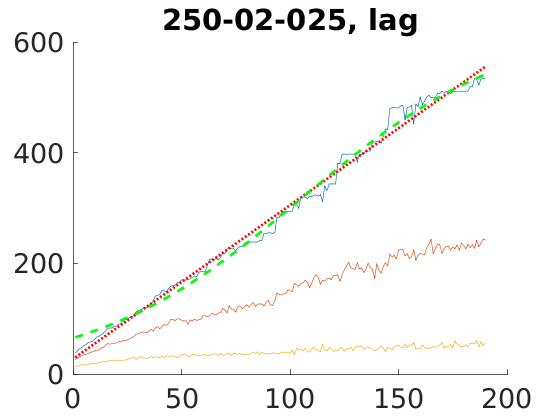

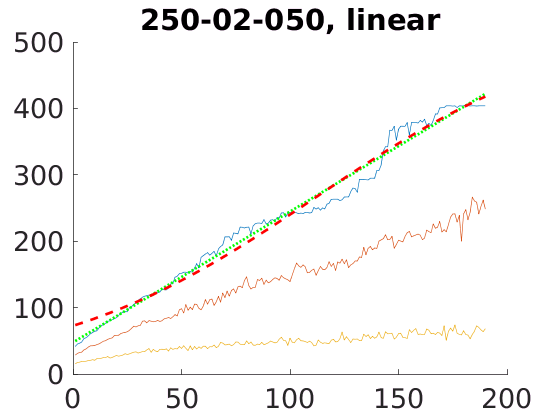

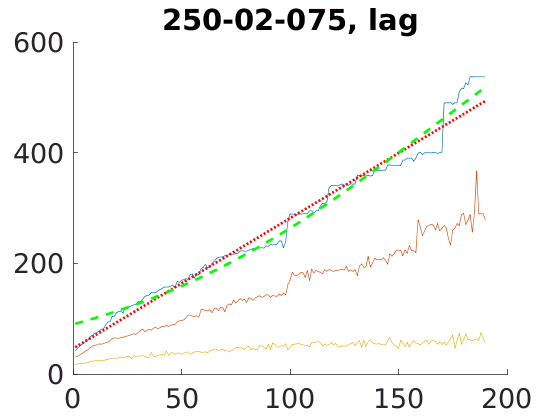

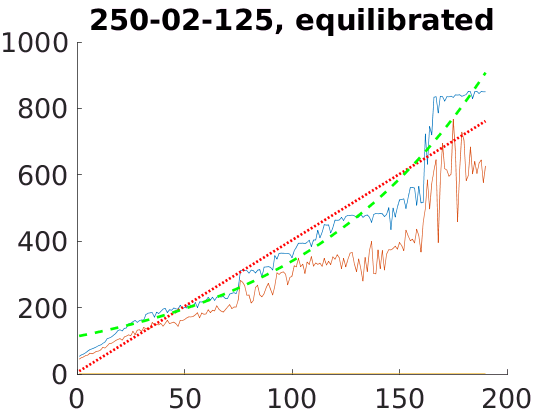

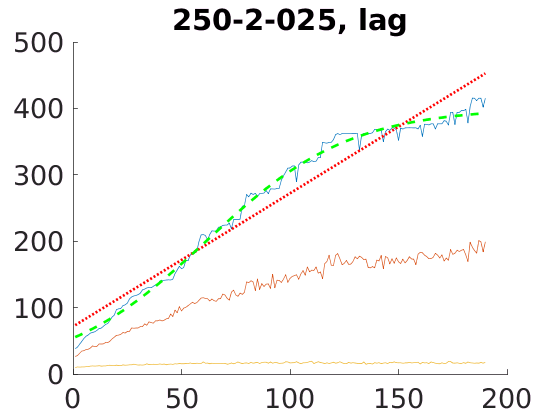

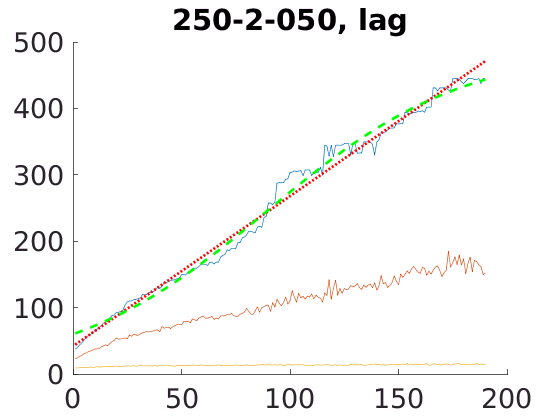

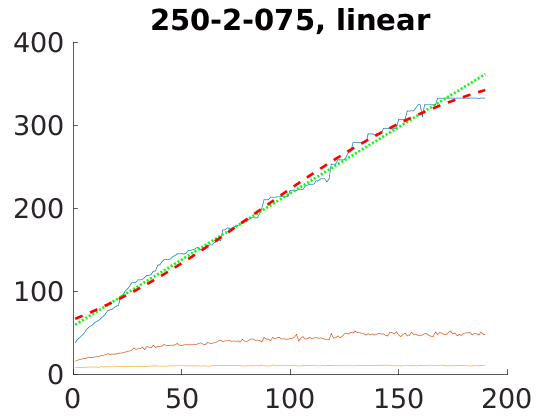

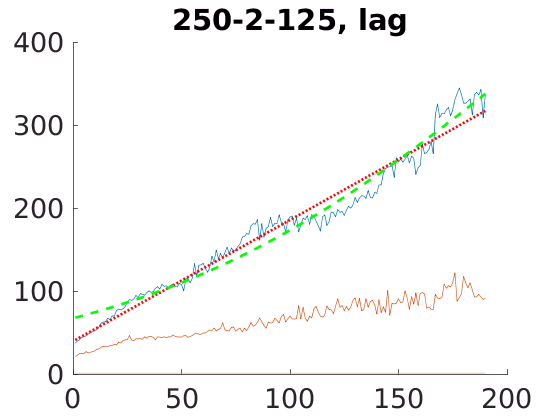

addpath('/home/rachael/Analysis_and_run_code/stats_analysis/');
sigmoid = fittype('k*(1/(1+exp(-(b*x-a))))','independent','x');
sp = [10,0.1,10000];
ctypes = {};

for i = 1:length(AAnames)
    for sc = 1:length(SCnames)
        for sig = 1:length(Signames)
            cMat = mu2contactMats{i}{sc}{sig};
            cMatO = mu2opticalMats{i}{sc}{sig};
            cMatA = mu2alignedMats{i}{sc}{sig};
            if ~isempty(cMat)
            figure()
            set(gca,'fontsize',20)
            hold on
            
            plot(cMat)
            plot(cMatO)
            plot(cMatA)
            
            mmu2s = mean(cMat,2);
            smu2s = std(cMat,[],2);
            if mmu2s(end)+smu2s(end) < 2
                ctypes{i}{sc}{sig} = 'no';
            %elseif mmu2s(end) > 0.9*10648
            %    ctypes{i}{sc}{sig} = 'max';
            else
                sp = [10,0.1,mmu2s(end)];
                %weights = 
                [sf,gsf] = fit((1:length(cMat))',mean(cMat,2),sigmoid,'StartPoint',sp);
                [lf,glf] = fit((1:length(cMat))',mean(cMat,2),'poly1');
                aicSig = akaike(3,length(cMat),gsf.sse);
                aicLin = akaike(2,length(cMat),glf.sse);
                if aicLin < aicSig
                    
                    plot(lf(1:length(cMat)),'g:','linewidth',2)
                    plot(sf(1:length(cMat)),'r--','linewidth',2)
                    ci = confint(lf);
                    if ci(1) <= 0
                       ctypes{i}{sc}{sig} = 'equilibrated';
                    else
                        ctypes{i}{sc}{sig} = 'linear';
                    end
                else
                    plot(lf(1:length(cMat)),'r:','linewidth',2)
                    plot(sf(1:length(cMat)),'g--','linewidth',2)
                    ci = confint(sf);
                    cil = confint(lf);
                    if cil(1) <=0
                        ctypes{i}{sc}{sig} = 'equilibrated';
                    elseif ci(1) <=0
                       ctypes{i}{sc}{sig} = 'equilibrated'; 
                    else
                       ctypes{i}{sc}{sig} = 'lag'; 
                    end
                 
                end
                
            end
            title([AAnames{i} '-' SCnames{sc} '-' Signames{sig} ', ' ctypes{i}{sc}{sig}])
            end
        end
    end
end

## Phase Diagram

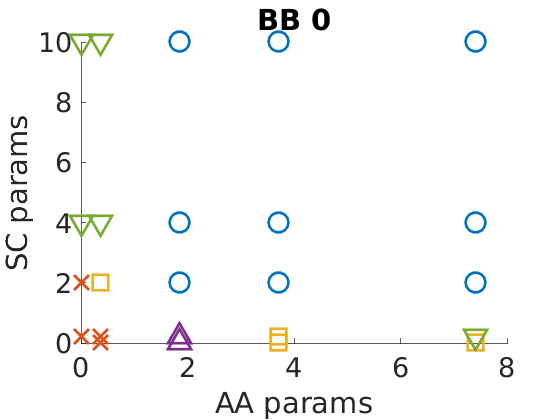

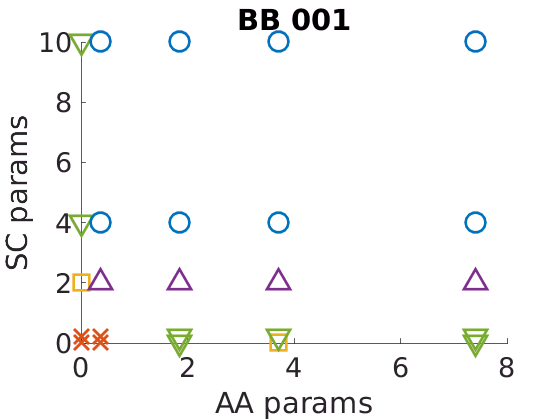

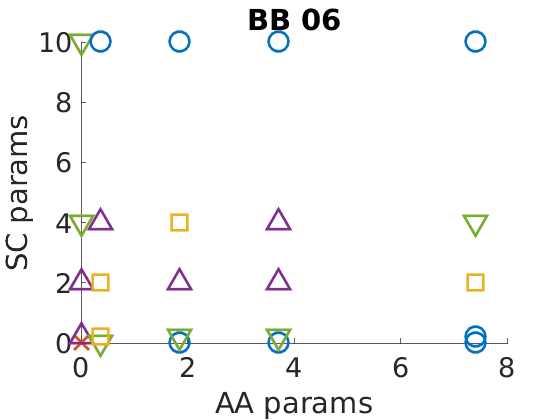

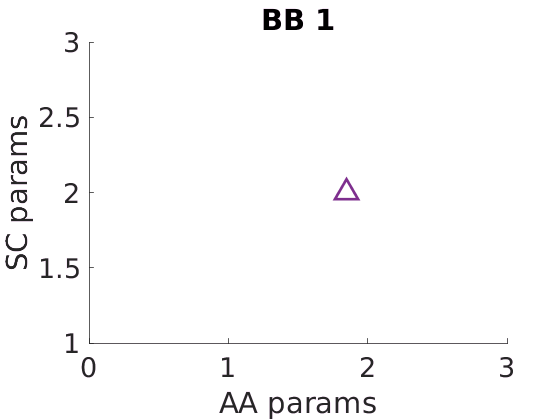

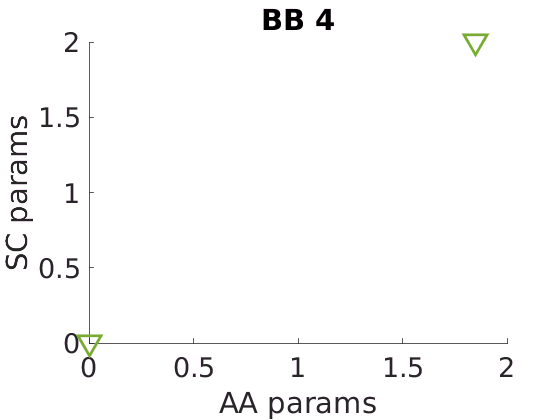

addpath('/home/rachael/Analysis_and_run_code/lab_notebook/CG_patchy/helper_fcns');
plotPhaseDiagram(Signames,AAnames,SCnames,mu2contactMats,ctypes,paramDict)